## **CBM-Toolbox Script for Reversal Learning Data**

This script fits reinforcement learning models to choice data from reversal learning using the Computational Behavioral Modeling toolbox by [Piray et al., 2019](https://journals.plos.org/ploscompbiol/article?id=10.1371/journal.pcbi.1007043)  that applies hierarchical Bayesian inference during concurrent model fitting. In order to run successfully, you need add the cbm-toolbox ('codes') to your matlab-path, and have the 'model_RL' script in the Reversal_Vol_CBM folder. The model script contains a standard Rescorla Wagner model-space with Single Update, individually weighted Double Update and full Double update, with one or two learning rates (win/loss), combined with a softmax (1 beta).    

## **1) Prepare data for cbm**

adapt the paths for your computer

clc 
clear all
close;

system = getenv('COMPUTERNAME');
if strcmp(system, 'C15MW-PS-FO-02') % Teresa's office pc
prefix = 'T:\owncloud\';
addpath(fullfile([prefix, 'cbm-master-original\cbm-master\codes']));
elseif strcmp(system,'C15MN-PS-FO-13') % Teresas laptop
prefix = 'C:\users\katthagt\owncloud\';
addpath(fullfile([prefix, 'cbm-master-original\cbm-master\codes']));
addpath(fullfile([prefix, '\Shared\Reversal_Vol\scripts_cbm\']));
cd(fullfile([prefix, '\Shared\Reversal_Vol\scripts_cbm\']));
input_path_CT = '\Users\katthagt\Owncloud\Shared\Reversal_Vol\SALAD_data\HC_Control\'; %behavioral data in mat files
input_path_ST = '\Users\katthagt\Owncloud\Shared\Reversal_Vo\SALAD_data\HC_Stress\'; 
else
prefix = '/Users/larawieland/Owncloud/'; % Lara's PC
addpath('/Users/larawieland/ownCloud/Shared/Reversal_Vol/scripts_cbm/'); % adapt
addpath('/Users/larawieland/Documents/Promotion/Modeling/cbm/codes/'); % adapt
cd(fullfile([prefix, '/Shared/Reversal_Vol/scripts_cbm/']));
input_path_CT = '/Users/larawieland/Owncloud/Shared/Reversal_Vol/SALAD_data/HC_Control/'; %behavioral data in mat files
input_path_ST = '/Users/larawieland/Owncloud/Shared/Reversal_Vol/SALAD_data/HC_Stress/'; 
end

% addpath('C:\Users\katthagt\ownCloud\Shared\NegSym\Modeling\hgfToolBox_v4.15');

% load data
input_CT =  dir([input_path_CT, '*WS.mat']);
input_ST =  dir([input_path_ST, '*WS.mat']);
data = {};
nmodels = 6;
nsubjects = length(input_CT);

% load data
input =  dir([input_path_CT, '*WS.mat']);
data = {};
nmodels = 6;
nsubjects = length(input);

% subject loop to store all individual choice data in cohensive input file needed for cbm
for sub = 1:length(input)
data{sub,1}.code   = input(sub).name(12:19);
data{sub,1}.T      = input(sub).name(18:19);
load([input_path_CT input(sub).name], 'R', 'A');
R = R(~isnan(A));  A = A(~isnan(A)); R(R==-1)=0; %check whether your model needs losses as 0 or -1
data{sub,1}.actions = A;
data{sub,1}.outcome = R;
end

% subject loop for individual choice data from both sessions within one file per subject

## 2) check if model is running correctly with random parameters (no actual fitting)

Note: The cbm files were modified, so that one learning script can fit different models depending on the model number, that is the third input now in the standard fitting function loglik = model_RL(parameters,subj, model_no). Check section 3 for amount of free parameters for each model.

Model numbers (model_no):

1 --> SU 1 alpha, 2 --> SU 2 alphas

3 --> iDU 1 alpha, 2 --> iDU 2 alphas

4 --> DU 1 alpha, 2 --> DU 2 alphas 

% loglik = model_RL(parameters,subj1)

subj1 = data{1}; 
parameters = randn(1,3); 
% F1 = model_RL(parameters,subj1,2),
[F1, traj] = model_nolearning_qbias(parameters,subj1)

Error using model_nolearning_qbias
Too many output arguments.

## 3) use cbm for initial model fitting and group prior estimation 

The function 'cbm_lap' fits every model to each subject data separately (i.e. in a non-hierarchical fashion, so that only (random) individuals are fitted first without any (fixed) group information)

It uses Laplace approximation needing a normal prior for every parameter ([see manual](file:///C:/Users/katthagt/ownCloud/cbm-master/manual.html)) with: 

mean = 0 and variance = 6.25. 

All parameters are normalized (-Inf to Inf), thus parameters between 0:1 need to be sigmoid-transformed (--> logit-space) and parameters > 0 must be exponential-transformed (log-space) in the beginning of the learning model-file.

crucial function: cbm_lap(data, @model, priors, output file,[ ], model_no)

v                = 6.25;    % variance is the same for all priors
% name output files
fname_RL = {};
fname_RL{1}='SU1al_CT.mat';  fname_RL{2}='SU2al_CT.mat'; fname_RL{3}='iDU1al_CT.mat'; 
fname_RL{4}='iDU2al_CT.mat'; fname_RL{5}='DU1al_CT.mat'; fname_RL{6}='DU2al_CT.mat'; 
fname_RL{7}='PH_CT.mat';     fname_RL{8}='nullmodel_nobeta.mat'; 

% set amount of priors for each model
prior(1)     = struct('mean', zeros(3,1),'variance',v);          % 2 free parameters (alpha, beta)
prior(2)     = struct('mean', zeros(4,1),'variance',v);          % 3 free parameters (alpha_rew, alpha_pun, beta) 
prior(3)     = struct('mean', zeros(4,1),'variance',v);          % 3 free parameters (alpha, kappa, beta)
prior(4)     = struct('mean', zeros(5,1),'variance',v);          % 4 free parameters (alpha_rew, alpha_pun, kappa, beta) 
prior(5)     = struct('mean', zeros(3,1),'variance',v);          % 2 free parameters (alpha, beta)
prior(6)     = struct('mean', zeros(4,1),'variance',v);          % 3 free parameters (alpha_rew, alpha_pun, beta) 
prior(7)     = struct('mean', zeros(5,1),'variance',v);          % 2 free parameters (alpha, beta)
prior(8)     = struct('mean', zeros(1,1),'variance',v);          % 3 free parameters (alpha_rew, alpha_pun, beta) 

models = {'@model_RL_SU1al_2betas', '@model_RL_SU2al_2betas','@model_RL_iDU1al_2betas', '@model_RL_iDU2al_2betas','@model_RL_DU1al_2betas', '@model_RL_DU2al_2betas', '@model_PH_1LR', '@model_nolearning_qbias_nobeta'};

cbm_lap(data, @model_RL_SU1al_2betas,  prior(1), char(fname_RL(1))); % last input for model number!

cbm_lap                                           29-Jan-2021 12:26:53
Number of samples: 28
Number of parameters: 3

Number of initializations: 21
----------------------------------------------------------------------


cbm_lap(data, @model_RL_SU2al_2betas,  prior(2), char(fname_RL(2))); % last input for model number!
cbm_lap(data, @model_RL_iDU1al_2betas, prior(3), char(fname_RL(3))); % last input for model number!
cbm_lap(data, @model_RL_iDU2al_2betas, prior(4), char(fname_RL(4)));% last input for model number!
cbm_lap(data, @model_RL_DU1al_2betas,  prior(5), char(fname_RL(5))); % last input for model number!
cbm_lap(data, @model_RL_DU2al_2betas,  prior(6), char(fname_RL(6))); % last input for model number!

cbm_lap(data, @model_PH_1LR,  prior(7), char(fname_RL(7))); % last input for model number!

cbm_lap                                           27-Jan-2021 16:51:09
Number of samples: 28
Number of parameters: 5

Number of initializations: 35
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
done :]


cbm_lap(data, @model_nolearning_qbias_nobeta,  prior(8), char(fname_RL(8))); % last input for model number!

cbm_lap                                           27-Jan-2021 16:50:57
Number of samples: 28
Number of parameters: 1

Number of initializations: 7
----------------------------------------------------------------------
Subject: 01
Subject: 02
Subject: 03
Subject: 04
Subject: 05
Subject: 06
Subject: 07
Subject: 08
Subject: 09
Subject: 10
Subject: 11
Subject: 12
Subject: 13
Subject: 14
Subject: 15
Subject: 16
Subject: 17
Subject: 18
Subject: 19
Subject: 20
Subject: 21
Subject: 22
Subject: 23
Subject: 24
Subject: 25
Subject: 26
Subject: 27
Subject: 28
done :]


## 5) hierarchical Bayesian inference: concurrent model fitting

Here, we use the parameters from step 3 as priors for concurrent model-fitting (all models are fitted within one step). Using hierarchical bayesian inference, random (individuals') parameters inform the fixed (group) parameters according to the likelihood of this model being the best model for the respective subject ("responsibility"). 

Central function: cbm_hbi(data,nmodels,fcbm_maps,fname_hbi);

% 2nd input: a cell input containing function handle to models (== @ before the name of the function)
% models = {@model_RL_SU1al_2betas, @model_RL_SU2al_2betas, @model_RL_iDU1al_2betas, @model_RL_iDU2al_2betas, @model_RL_DU1al_2betas, @model_RL_DU2al_2betas, @model_PH_1LR, @model_nolearning_qbias_nobeta};
models = {@model_RL_SU1al_2betas, @model_RL_SU2al_2betas, @model_RL_iDU1al_2betas, @model_RL_iDU2al_2betas, @model_RL_DU1al_2betas, @model_RL_DU2al_2betas};
% models = {@model_nolearning_qbias, @model_nolearning_qbias_1beta, @model_nolearning_qbias_nobeta};
% 3rd input: another cell input containing file-address to files saved by
% cbm_lap, note that they corresponds to models (so pay attention to the order)
% fcbm_maps = {'SU1al_CT.mat','SU2al_CT.mat','iDU1al_CT.mat','iDU2al_CT.mat','DU1al_CT.mat','DU2al_CT.mat'};
fcbm_maps = {'SU1al_CT.mat','SU2al_CT.mat','iDU1al_CT.mat','iDU2al_CT.mat','DU1al_CT.mat','DU2al_CT.mat', 'PH_CT.mat','nullmodel_nobeta.mat'};
% fcbm_maps = {'nullmodel_2beta.mat', 'nullmodel_1beta.mat', 'nullmodel_nobeta.mat'};
% 4th input: a file address for saving the output
fname_hbi = 'hbi8models_CT.mat';

cbm_hbi(data,models,fcbm_maps,fname_hbi);

Undefined function or variable 'data'.

## 6) Plot the hbi parameters

As in step 4, display the fitted parameters as implemented in the toolbox function: 'cbm_hbi_plot(fname_hbi, model_names, param_names, transform, model of interest)'

1st input is the file-address of the file saved by cbm_hbi

2nd input: a cell input containing model names

3rd input: another cell input containing parameter names of the winning model 

4th input: another cell input containing transformation function associated with each parameter of the winning model

5th input: optional, indicates model of interest

fname_hbi = 'hbi_8models_CT.mat'; % 1st input is the file-address of the file saved by cbm_hbi
hbi = load('hbi_8models_CT.mat');
cbm = hbi.cbm;
cbm.output 

ans = struct with fields:
                     parameters: {8×1 cell}
                 responsibility: [28×8 double]
                     group_mean: {1×8 cell}
    group_hierarchical_errorbar: {1×8 cell}
                model_frequency: [3.5039e-04 0.1851 2.3269e-04 0.3772 1.7857e-06 0.4371 3.2326e-06 1.7411e-05]
                exceedance_prob: [9.0000e-06 0.0207 1.2000e-05 0.3572 1.3000e-05 0.6220 1.4000e-05 1.9000e-05]
      protected_exceedance_prob: [1.6000e-05 0.0209 1.9000e-05 0.3573 8.0000e-06 0.6217 1.1000e-05 1.5000e-05]



[M,I]=max(cbm.output.exceedance_prob);   % find the model with the highest exceedance probability index I

param_names(1).p        = {'alpha', 'beta win', 'beta loss' };
param_names(1).transform= {'sigmoid', 'exp', 'exp'};
param_names(2).p        = {'alpha reward', 'alpha loss', 'beta win', 'beta loss'};
param_names(2).transform= {'sigmoid', 'sigmoid', 'exp', 'exp'};
param_names(3).p        = {'alpha', 'kappa', 'beta win', 'beta loss', };
param_names(3).transform= {'sigmoid', 'sigmoid', 'exp', 'exp'};
param_names(4).p        = {'alpha reward', 'alpha loss', 'kappa', 'beta win', 'beta loss'};
param_names(4).transform= {'sigmoid','sigmoid','sigmoid','exp','exp'};
param_names(5)   = param_names(1);
param_names(6)   = param_names(2);

cbm_hbi_plot(fname_hbi, fname_RL, param_names(I).p, param_names(I).transform, I) % this function creates a model comparison plot (exceednace probability and model frequency) as well as

Unrecognized function or variable 'fname_RL'.

## 4) Check the fitted parameters

Note that the parameters are normalized before saving, and not to be back-transformed to make sense in the model. 

params contains all fitted parameters (subjects, parameters, model_no):

1st column: alpha_both     2nd alpha_reward     3rd alpha_loss    4th kappa     5th beta 

You can pick between the parameters from the individually fitted models and the ones from hierarchical Bayesian inference with "whichfit" 

params = NaN(nsubjects, 8, nmodels);
whichfit = 2; % for cbm, 2 for hbi
 
if whichfit == 2
     fname_hbi = load('hbi_RL_fullmodelspace_CT.mat');
     cbm = fname_hbi.cbm;
end

for i = 1:nmodels
if whichfit == 1
    model_name = load(fname_RL{i});
    cbm = model_name.cbm;
    nd_params = cbm.output.parameters;
else
    nd_params = cbm.output.parameters{i};
    params(:,6,i) = cbm.output.responsibility(:,i);
end
        
if mod(i,2)
params(:,1,i)= 1./(1+exp(-nd_params(:,1)));  % alpha
    if (i == 1 | i == 5)
params(:,5,i)= exp(nd_params(:,2));     % beta
    elseif i==3
params(:,4,i)= 1./(1+exp(-nd_params(:,2))); % kappa
params(:,5,i)= exp(nd_params(:,3));        % beta
    end
elseif ~mod(i,2)
params(:,2:3,i)= 1./(1+exp(-nd_params(:,1:2))); % alpha_win, alpha_loss
    if (i == 2 | i == 6)
params(:,5,i)= exp(nd_params(:,3));     % beta
    elseif i==4
params(:,4,i)= 1./(1+exp(-nd_params(:,3))); % kappa
params(:,5,i)= exp(nd_params(:,4));        % beta
    end
end
clear nd_params
end

% % Plot parameters

for i = 1:3     %number of max free parameters
figure; hold on;
if i == 1       % alpha   
for j = 1:nmodels 
    subplot(3,2,j);
    if mod(j,2)
    scatter((1:nsubjects),params(:,1,j));
    else
    scatter((1:nsubjects),params(:,2,j)); hold on;
    scatter((1:nsubjects),params(:,3,j), 'r'); hold off;    
    end
    if j==1
    title('1. SU1alpha: alpha');
    elseif j==2
    title('2. SU2alphas: alpha reward (blue) and alpha loss(red)');
    elseif j==3
    title('3. iDU1alpha: alpha');
    elseif j==4
    title('4. iDU2alphas: alpha reward (blue) and alpha loss(red)');
    elseif j==5
    title('5. DU1alpha: alpha');
    elseif j==6
    title('6. DU2alphas: alpha reward (blue) and alpha loss(red)');
    end
    
end
elseif i ==2 % kappa
for j = 1:nmodels 
    if j==3
    subplot(2,1,1)
    title('3. iDU1alpha: kappa');
    scatter((1:nsubjects),params(:,4,j));
    elseif j==4
    subplot(2,1,2)
    title('4. iDU2alphas: kappa'); 
    scatter((1:nsubjects), params(:,4,j));
    end
end
    
elseif i ==3 % beta
    for j = 1:nmodels   
    subplot(3,2,j);
        scatter((1:nsubjects), params(:,5,j));
        if j==1
        title('1. SU1alpha: beta');
        elseif j==2
        title('2. SU2alphas: beta');
        elseif j==3
        title('3. iDU1alpha: beta');
        elseif j==4
        title('4. iDU2alphas: beta');
        elseif j==5
        title('5. DU1alpha: beta');
        elseif j==6
        title('6. DU2alphas: beta');
        end
    end
end    
    hold off;
end

## 5. Compare group parameters and model comparison

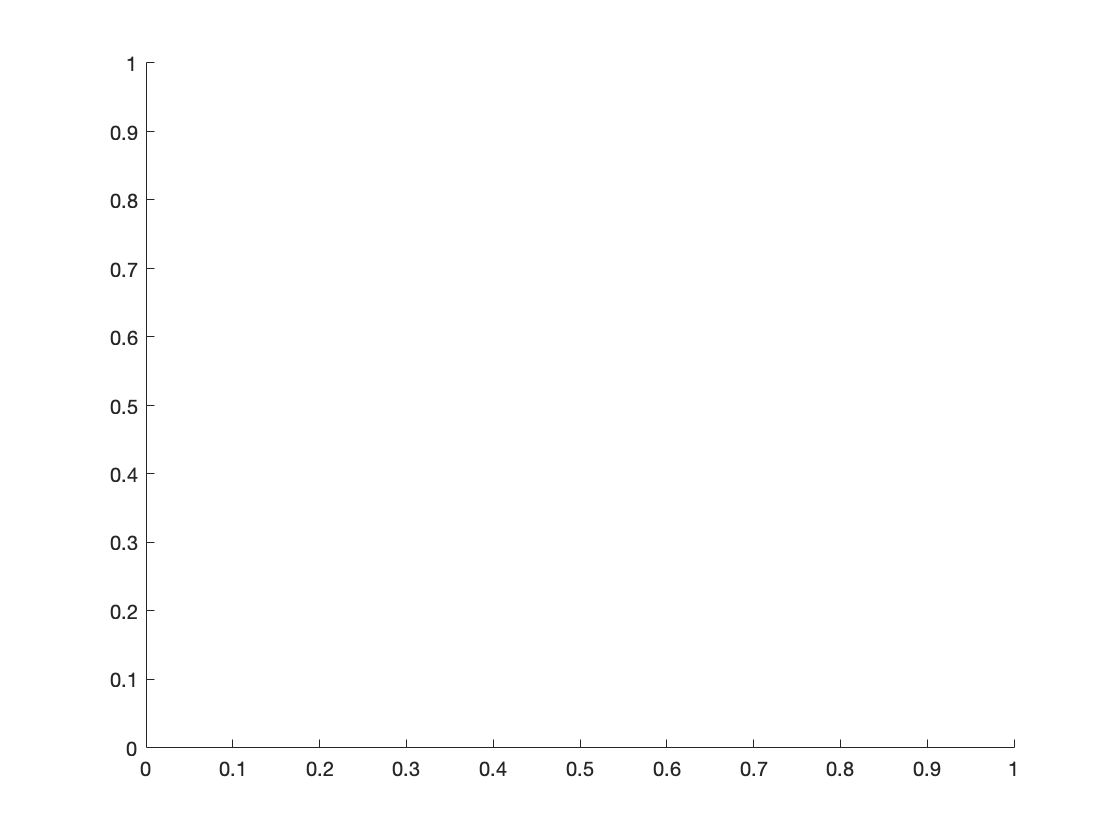

hold off; figure 

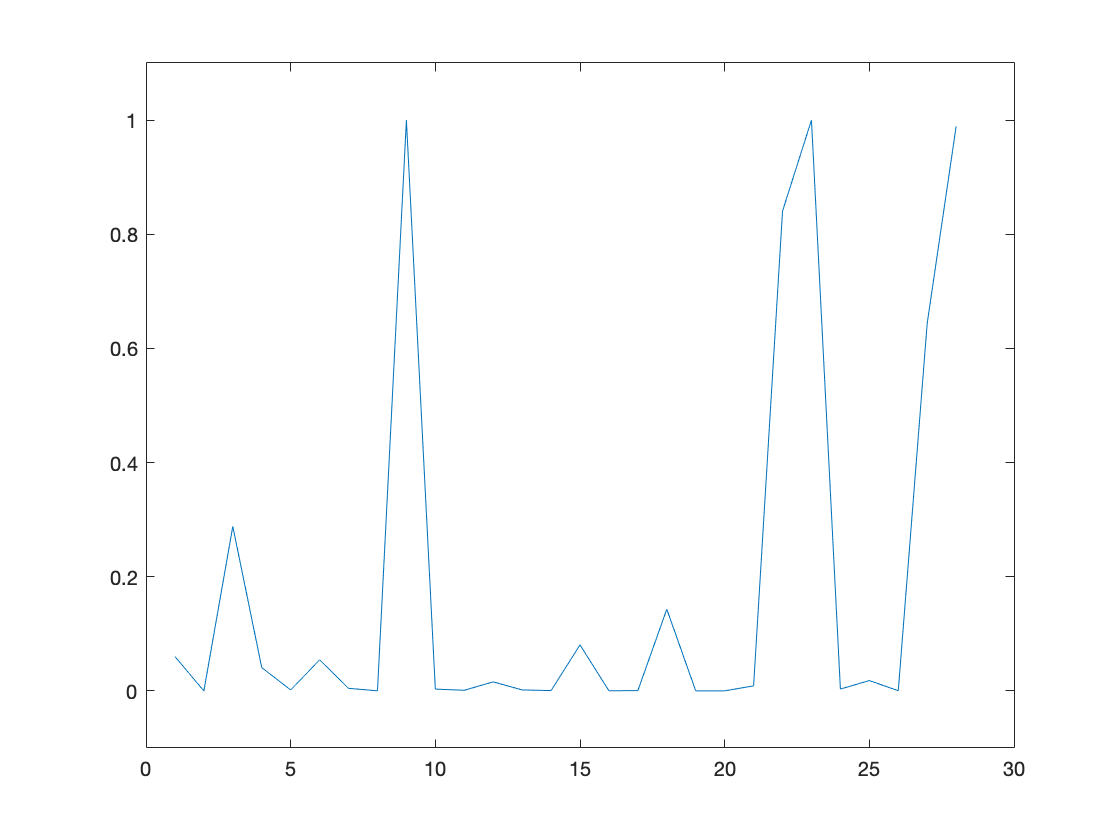

parameters_RL = cbm.output.parameters{1};
parameters_dualRL = cbm.output.parameters{2};
responsibility = cbm.output.responsibility;
plot(responsibility(:,2)); ylim([-.1 1.1]);


% estimate protected exceedance probabilities (taking into account the null hypothesis that no model in the model space is most likely across the population (i.e. any difference between model frequencies is due to chance).
fname_hbi = 'hbi_8models_CT.mat'; % file-address of the file saved by cbm_hbi
cbm_hbi_null(data,fname_hbi); % updates the upper file now containing  the pxps

Unrecognized function or variable 'data'.

## 6. Plot model responsibility by patient group

(numbering based on the Leipzig data)

fname_hbi = load('hbi_RL_fullmodelspace.mat');
cbm = fname_hbi.cbm; 
resp = cbm.output.responsibility;

group = group'; group_idx = str2double(group);

for i = 1:nmodels
HC(i)  = [mean(resp(group_idx==0,i))];
PDI(i) = [mean(resp(group_idx==5,i))];
AUD(i) = [mean(resp(group_idx==10,i))];
Szm(i) = [mean(resp(group_idx==20,i))];
Szu(i) = [mean(resp(group_idx==21,i))];
BED(i) = [mean(resp(group_idx==30,i))];
OCD(i) = [mean(resp(group_idx==40,i))];
end

figure
for i = 1:nmodels
subplot(3,2,i)
scatter(1:40,resp(group_idx==20,i))
end



% 
% figure
% subplot(2,2,1)
% bar(HC)
% title('HC N=89')
% subplot(2,2,2)
% bar(AUD)
% title('AUD N=42')
% subplot(2,2,3)
% bar(BED)
% title('BED N=22')
% subplot(2,2,4)
% bar(OCD)
% title('OCD N=30')